# Building my first simulink file

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours. However, the real world is full of non-linear components and characteristics such as saturations, switches and non-simple shapes. In such cases non-linear models are needed and simulink is an ideal tool to capture this.

This manual is in support of an app ***myfirstsimulink_control101.mlapp*** which gives a rapid introduction to some basic simulink components that students on a systems and control course may wish to use, and also, an opportunity to set up the simulation to send the simulation data to the workspace for neat plotting and analysis.

This livescript app makes use of the following files which are part of the toolbox:

- myfirstsimulinkfile_control101.slx  (for task 1)

- myfirstsimulinkfileb_control101.slx (for task 2)

- myfirstsimulinkfilec_control101.slx  (for task 3)

- myfirstsimulinkfile_control101_task1.slx (blank file for students to edit)

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**The next logical files are a sequence of case studies:**

- *intro_to_simulink_for_system_behaviour*

- *car_suspension_simulink_control101   *

- *heating_system_simulink_control101 *

- *position_system_simulink_control101 *

- *hydraulic_system_simulink_control101     *

- *submersible_simulink_control101  *      

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Introduction to the app

- Introductory task with a model, gain, source and a sink

- Forming vectors of outputs

- Introducing feedback loops

## 1. Introduction to the app

When  the app is opened (see Figure 1), this manual and a draft simulink file (Figure 3) are opened automatically. This simulink file has the name ***myfirstsimulinkfile_task1_mycopy.slx*** and will be open in the current working directory for which it is assumed the user has edit access. The user makes edits to this simulink file and then uses the compare task buttons to check their work. A concise summary of any errors will appear in the yellow box.

The green drop down menu in the bottom right displays the required block diagrams and the purple boxes summarise the requirements.

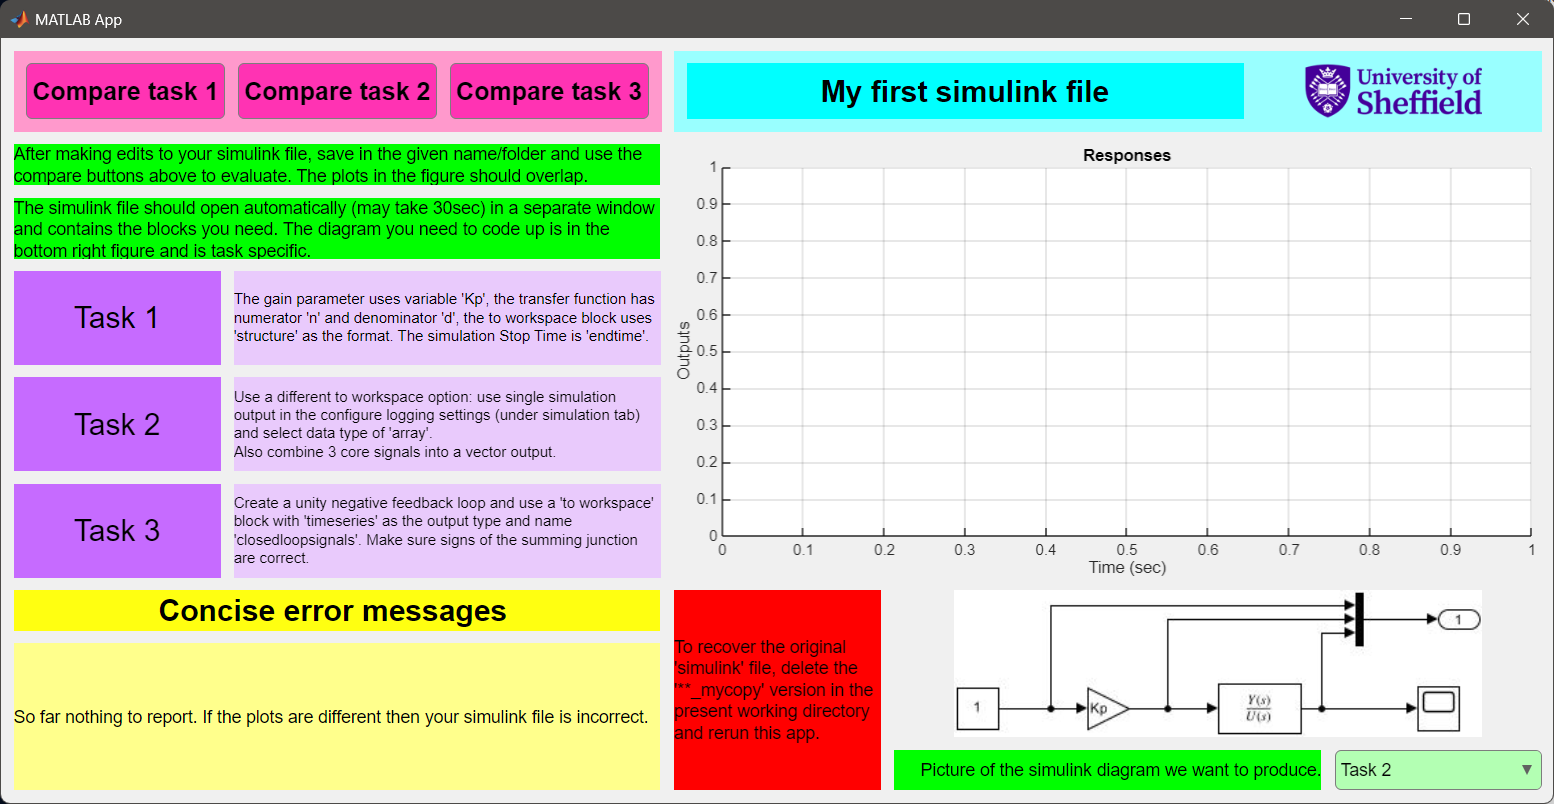

**Figure 1:** The app interface with summary instructions and pink buttons to test your work. 

## 2. Simple open-loop simulation

This task is to enable familiarisation with a common transfer function model block, a source which is a step input and some sinks (a scope and a to workspace block). Looking at the block diagram below it is hopefully self evident what is happening:

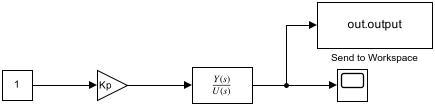

**Figure 2**: Screen capture of ***myfirstsimulinkfile_control101.slx***

The task here is for users to build this simulink file, but for convenience a blank template (Figure 2) should open with all the components you need - this has the name ***myfirstsimulinkfile_control101_task1_mycopy.slx*** and will be open in the current working directory. However, you will need to change some of the settings.

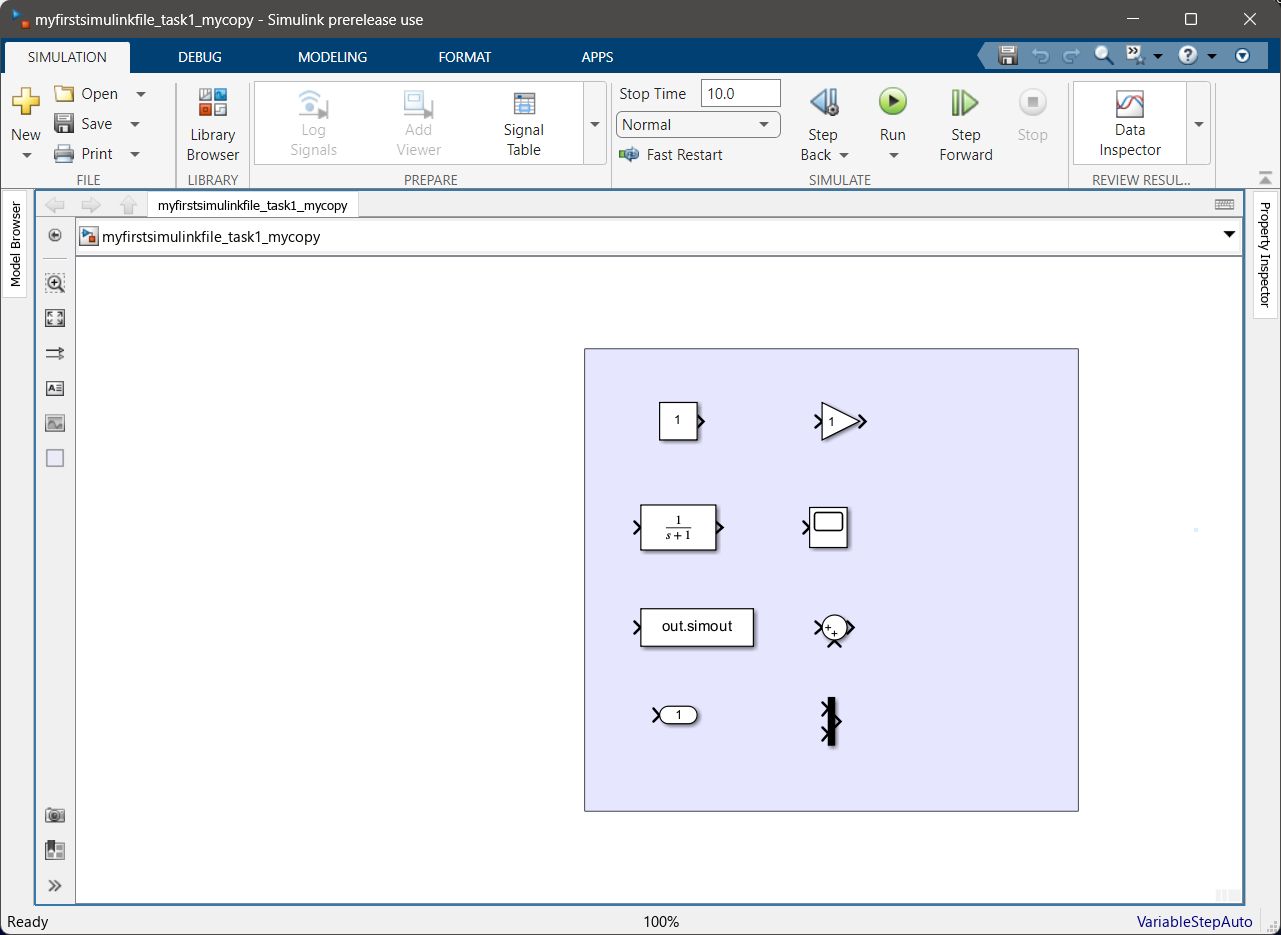

**Figure 3**: Blank template which should open automatically when you run the file: ***myfirstsimulink.mlapp***

- Build figure 1 using the blocks provided in the file shown in Figure 2. 

- Do not change the file name (***myfirstsimulinkfile_control101_task1_mycopy.slx) ***or location when  you save changes.

- Use the pink 'compare task 1' button to check whether your updated simulink file is correct.

- Changes required to the block settings (double click on blocks to open) are illustrated in the figures below. The gain parameter uses variable 'Kp', the transfer function has numerator 'n' and denominator 'd', the to workspace block uses 'structure' as the format. The simulation Stop Time is 'endtime'. 

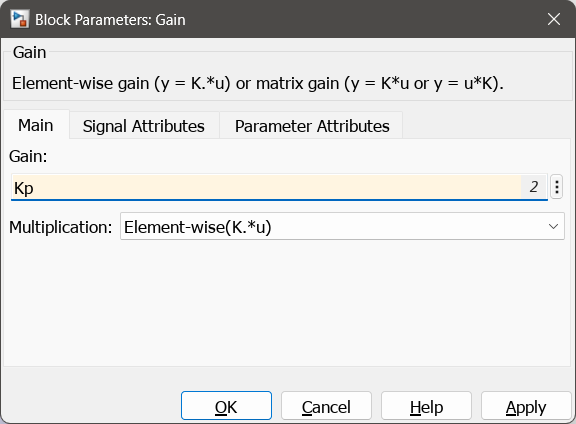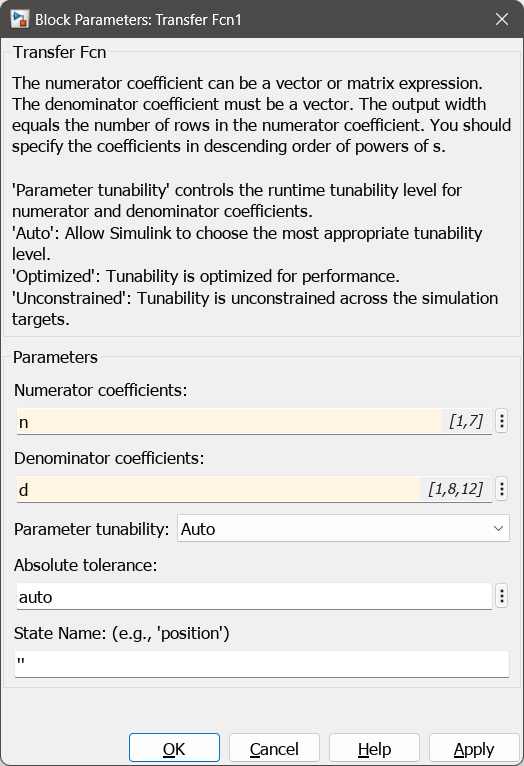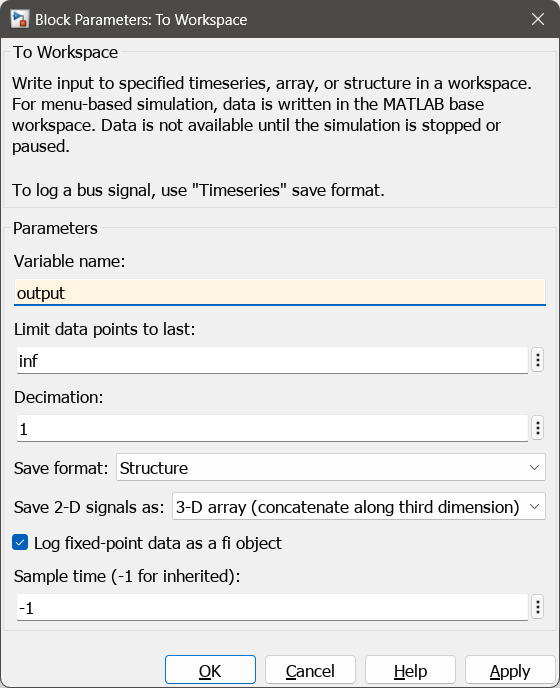

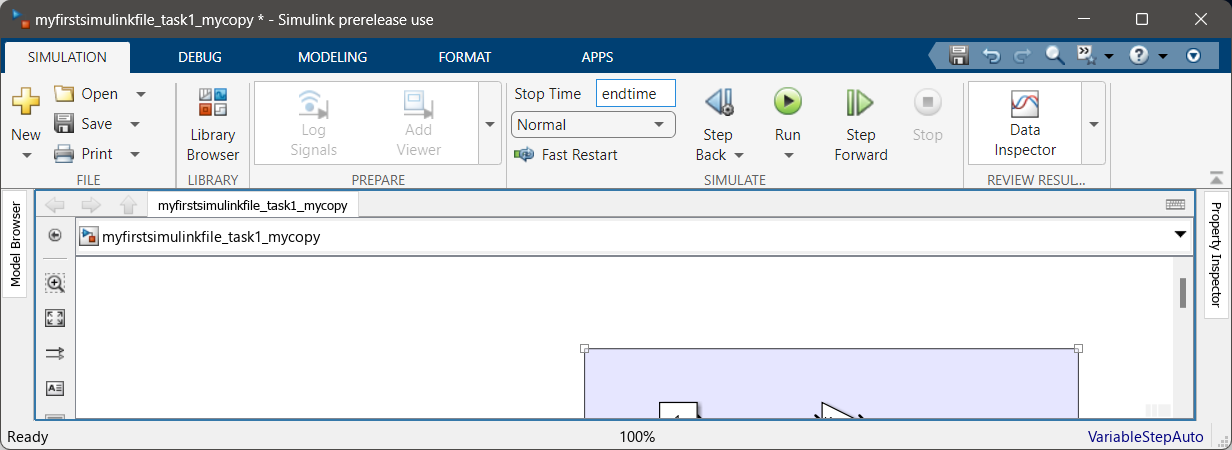

If the simulink file has been created correctly, it can be run and the outputs plotted from the workspace with the following commands (note we need to ensure the variables are defined in the workspace first). 

The code below uses the supplied simulink file, so comment this out and replace with the file you have created.

% define parameters
n =[1 7]; % Model numerator
d =[1 8 12]; % model denominator
endtime = 3; % length of simulation
Kp = 2; % value of gain


% y=sim('myfirstsimulinkfile_control101_task1_mycopy.slx');  % student file
y = sim('myfirstsimulinkfile_control101') % pre-prepared file

y =   Simulink.SimulationOutput:

                 output: [1x1 struct] 
                   tout: [55x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


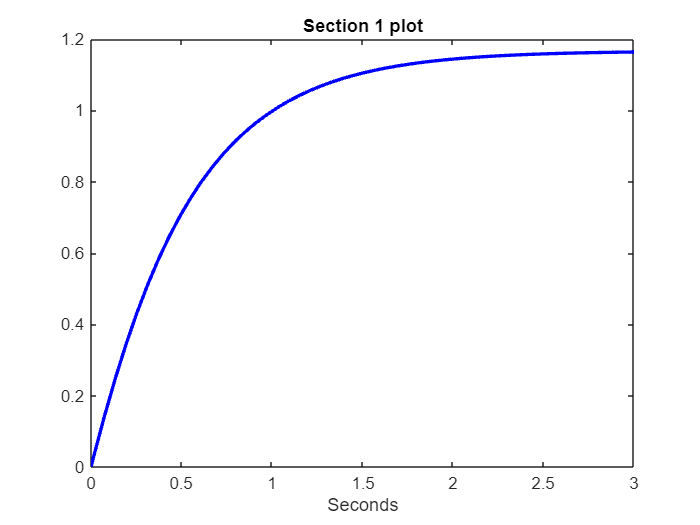

plot(y.tout,y.output.signals.values,'b','linewidth',2);
xlabel('Seconds')
title('Section 1 plot')

**Remark**: You can also run the simulink file from the simulink window with the run button as long as all the required parameters have been defined in the workspace.

## 2 Collate all the important states into a vector and use a different output option

The second task involves building the following block diagram where 3 signals are combined into a single vector using the 'mux' block and then send to the workspace and scope. For the app to work, do not change the file name (***myfirstsimulinkfile_control101_task1_mycopy.slx)*** or location when  you save changes.

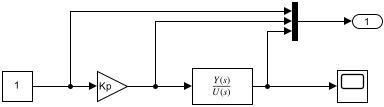

**Figure 4.** Creating a vector of states

The easiest way to do this is to begin from the simulink file of the previous section and add in the 'mux' block to combine the desired states. More details (see figures below) involve: Use a different to workspace option: use single simulation output in the configure logging settings (under simulation tab) and select data type of 'array'.  

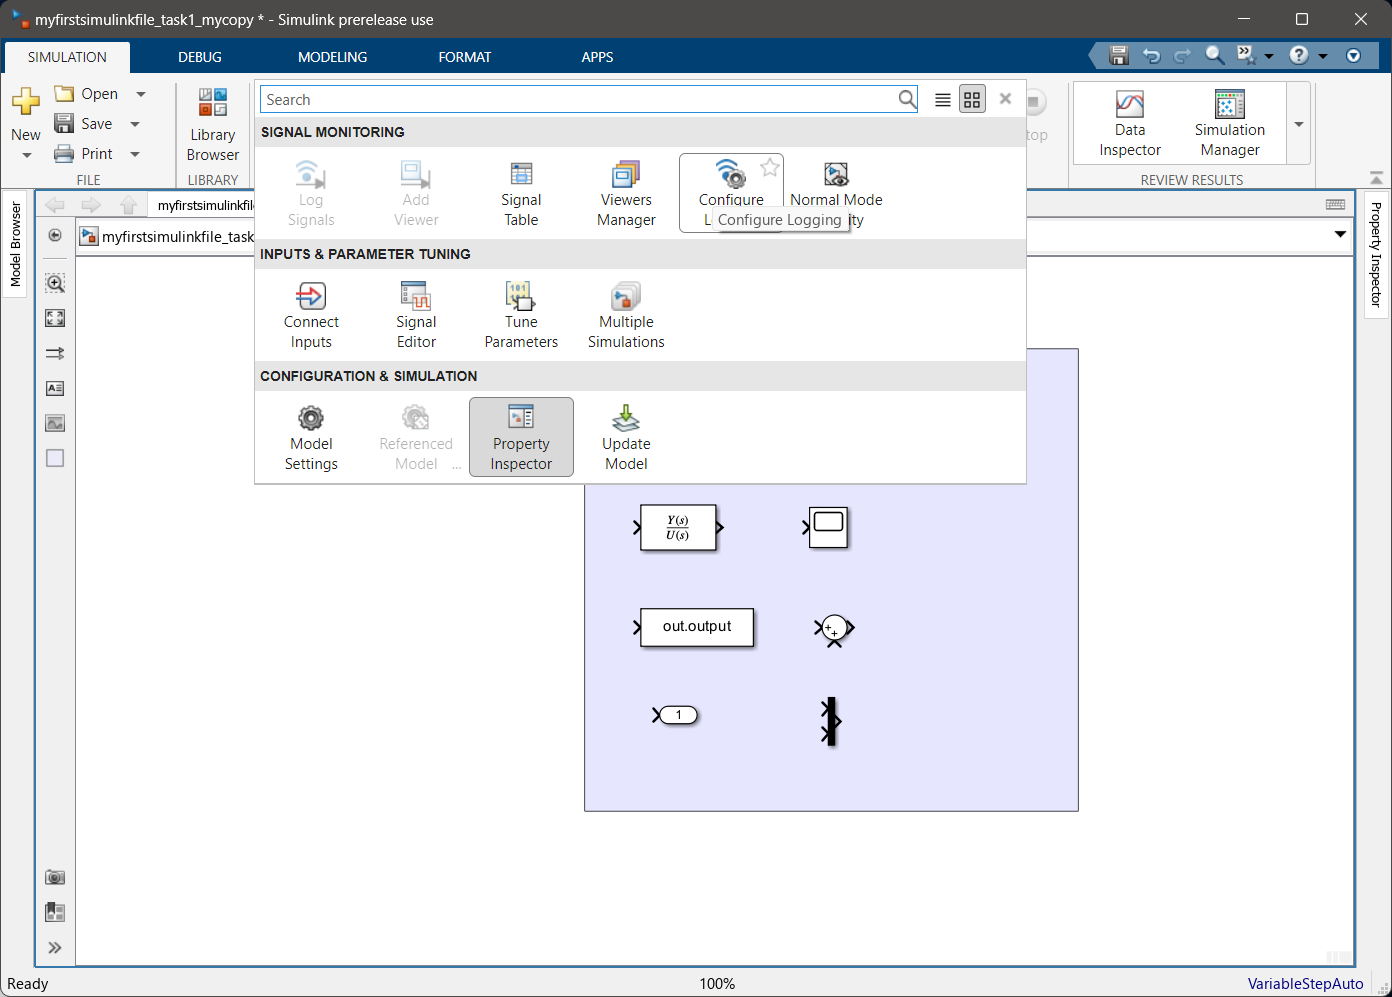

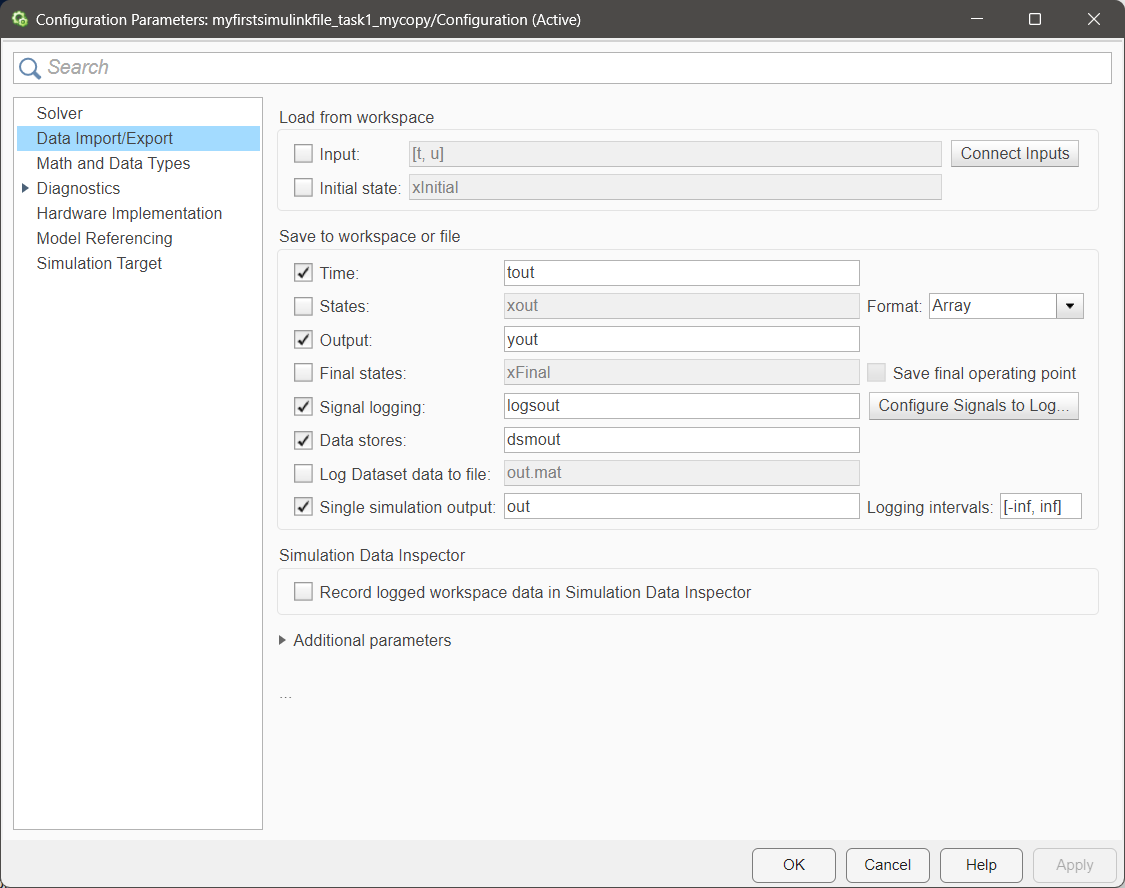

If the simulink file has been created correctly, it can be run and the outputs plotted from the workspace with the following commands (note we need to ensure the variables are defined in the workspace first).

The code below uses the supplied simulink file, so comment this out and replace with the file you have created.

% define parameters
n =[1 7]; % Model numerator
d =[1 8 12]; % model denominator
endtime = 3; % length of simulation
Kp = 2; % value of gain

% y2=sim('myfirstsimulinkfile_control101_task1_mycopy.slx');  % student file
y2 = sim('myfirstsimulinkfileb_control101') % pre-prepared file

y2 =   Simulink.SimulationOutput:

                   tout: [55x1 double] 
                   yout: [55x3 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


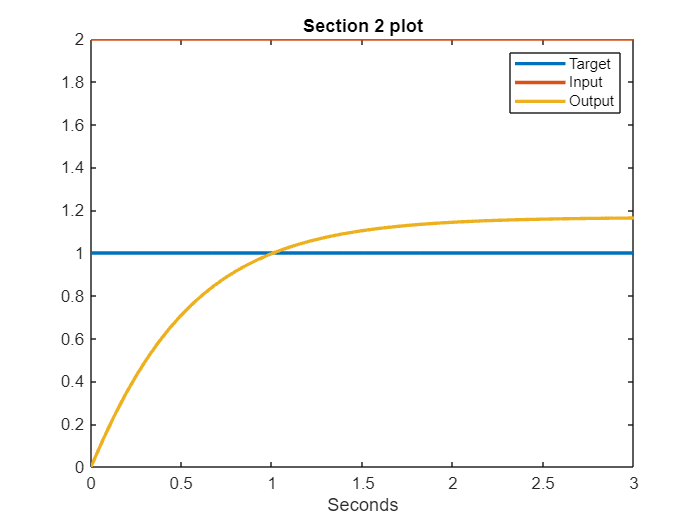

plot(y2.tout,y2.yout,'linewidth',2);
legend('Target','Input','Output')
xlabel('Seconds')
title('Section 2 plot')

## 3 Create and simulate a feedback loop 

The third task involves building the following block diagram where a simple feedback loop is constructed and selected signals are combined into a single vector using the 'mux' block and then sent to the workspace and scope. For the app to work, do not change the file name (***myfirstsimulinkfile_control101_task1_mycopy.slx)*** or location when  you save changes.

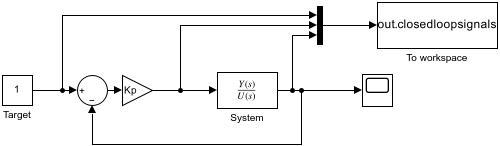

**Figure 5.** Creating a feedback loop in simulink

In summary, create a unity negative feedback loop and use a 'to workspace' block with 'timeseries' as the output type and name 'closedloopsignals'. Make sure signs of the summing junction are correct.The easiest way to do this is to begin from the simulink file of the previous section and add the summing junction and required 'to workspace' block. More details (see figure below) involve.

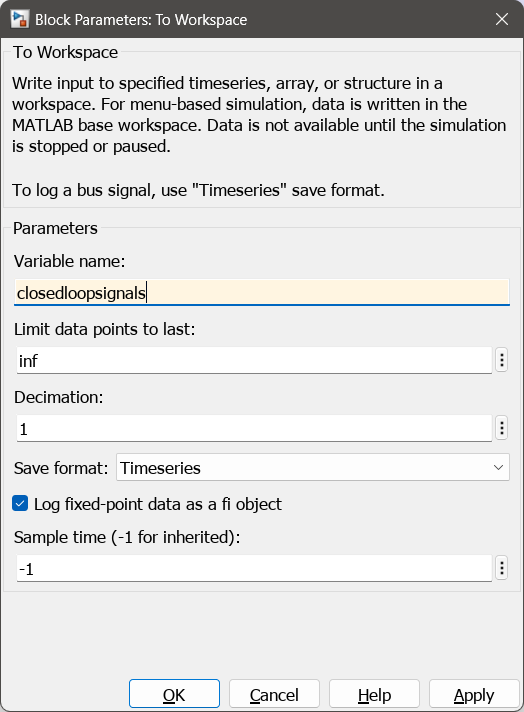

If the simulink file has been created correctly, it can be run and the outputs plotted from the workspace with the following commands (note we need to ensure the variables are defined in the workspace first).

The code below uses the supplied simulink file, so comment this out and replace with the file you have created.

% define parameters
n =[1 7]; % Model numerator
d =[1 8 12]; % model denominator
endtime = 3; % length of simulation
Kp = 2; % value of gain

% y3=sim('myfirstsimulinkfile_control101_task1_mycopy.slx');  % student file
y3 = sim('myfirstsimulinkfilec_control101') % pre-prepared file

y3 =   Simulink.SimulationOutput:

      closedloopsignals: [1x1 timeseries] 
                   tout: [55x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


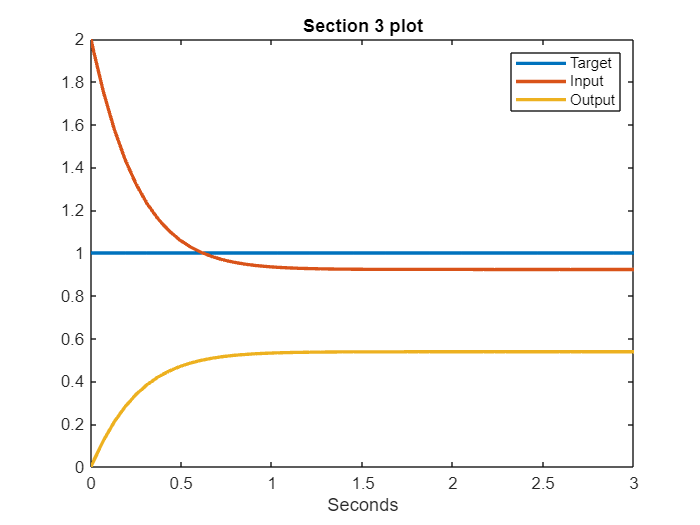

plot(y3.closedloopsignals.Time,y3.closedloopsignals.Data,'linewidth',2);
legend('Target','Input','Output')
xlabel('Seconds')
title('Section 3 plot')